clear all

clc

## Funwork 5

Phillipp Gery

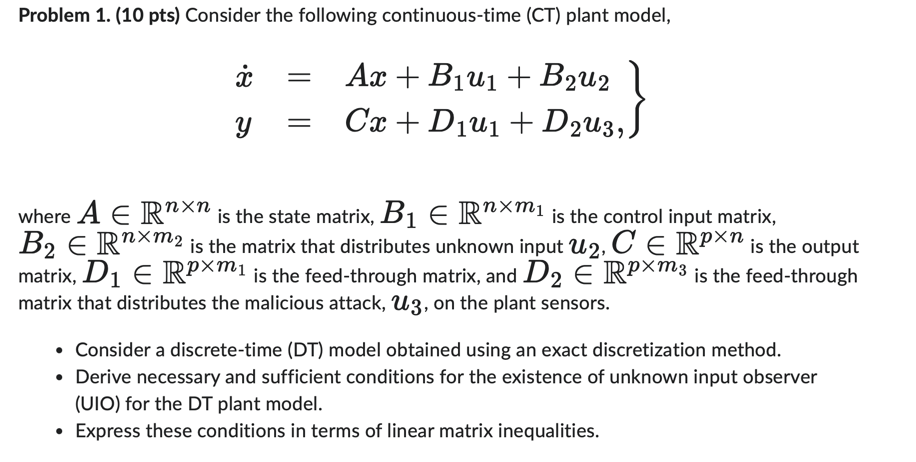

### 1.1

Given the Continuous-Time (CT) plant model:


$$$$\dot{x}(t) = Ax(t) + B_1 u_1(t) + B_2 u_2(t)$$
$$y(t) = Cx(t) + D_1 u_1(t) + D_2 u_3(t)$$$$


 to Discreate model:


$$$$x[k+1] = A_d x[k] + B_{1d} u_1[k] + B_{2d} u_2[k]$$
$$y[k] = C x[k] + D_1 u_1[k] + D_2 u_3[k]$$$$


where :


$$$$A_d = e^{A T_s}$$
$$B_{1d} = \left( \int_{0}^{T_s} e^{A\tau} d\tau \right) B_1$$
$$B_{2d} = \left( \int_{0}^{T_s} e^{A\tau} d\tau \right) B_2$$$$


Resulting in the DT model:


$$$$x[k+1] = A_d x[k] + B_{1d} u_1[k] + B_{2d} u_2[k]$$
$$y[k] = C x[k] + D_1 u_1[k] + D_2 u_3[k]$$$$


### 1.2 Necessary and Sufficient Conditions

#### first


$$$$x[k] = x[k] - M y[k] + M y[k]$$
$$


Subs


$$$y[k] = C x[k] + D_1 u_1[k] + D_2 u_3[k]$$$


into


$$$$x[k] = x[k] - M(C x[k] + D_1 u_1[k] + D_2 u_3[k]) + M y[k]$$
$$


manipulate


$$$$x[k] = (I - MC)x[k] - M D_1 u_1[k] - M D_2 u_3[k] + M y[k]$$$$


#### Condition 1:

To eliminate the influence of u_3[k] :


$$$$M D_2 = 0$$
$$


If this holds, the state equation simplifies to:


$$$$x[k] = \underbrace{(I - MC)x[k]}_{z[k]} + M (y[k] - D_1 u_1[k])$$$$


transformed state:


$$$z[k] = (I - MC)x[k]$.$$


Next, dynamics of z[k] to bet rid of u_2[k]


$$$$z[k+1] = (I - MC) x[k+1]$$$$


Subs


$$$x[k+1] = A_d x[k] + B_{1d} u_1[k] + B_{2d} u_2[k]$$$


into


$$$$z[k+1] = (I - MC)(A_d x[k] + B_{1d} u_1[k] + B_{2d} u_2[k])$$
$$


manipulate


$$$$z[k+1] = (I - MC)(A_d x[k] + B_{1d} u_1[k]) + (I - MC)B_{2d} u_2[k]$$
$$


resulting in 

#### Condition 2 :


$$$$(I - MC)B_{2d} = 0$$$$



$$

$$ M C B_{2d} = B_{2d}$$$$


#### Togetter:

We can combine these two equations into a single block matrix equation:


$$M \left[ \begin{array}{cc} C B_{2d} & D_2 \end{array} \right] = \left[ \begin{array}{cc} B_{2d} & 0 \end{array} \right]$$


Witch implies:


$$\text{rank}\left[ \begin{array}{cc} C B_{2d} & D_2 \\ B_{2d} & 0 \end{array} \right] = \text{rank}\left[ \begin{array}{cc} C B_{2d} & D_2 \end{array} \right]
$$


This is the **Necessary and Sufficient Condition** for the existence of the UIO 1.

If the rank condition is satisfied, calc M as:


$$M = \left[ \begin{array}{cc} B_{2d} & 0 \end{array} \right] \left[ \begin{array}{cc} C B_{2d} & D_2 \end{array} \right]^{\dagger}$$


M is determined, we define the system matrix A1


$$$$A_1 = (I - MC)A_d$$
$$


The observer exists if and only if the pair (C, A_1) is detectable. This ensures we can find a gain matrix L such that the matrix 

(A_1 - LC) 

is Schur stable.


$$$T = PL$


$$


### 1.3 N&S Cond. in LMI

Therfore:


$$$$A_1 = (I - MC)A_d$$
$$


 estimation error converges to zero asymptotically if 

(A_1 - LC)  is stable.

displayed as Lyaponov function:


$$$(A_1 - LC)^T P (A_1 - LC) - P < 0$ 

$$


witch is the shurr complemt of :


$$\left[ \begin{array}{cc} -P & A_1^T P - C^T T^T \\ P A_1 - T C & -P \end{array} \right] < 0$$


resulting in:

LMI Conditions:

for CT:

The UIO exists if there exist a p.d. P and a T such that

- 
$$$$P > 0$$
$$


- 
$$$$\left[ \begin{array}{cc} -P & A_1^T P - C^T T^T \\ P A_1 - T C & -P \end{array} \right] < 0$$
$$


therfore:


$$$L = P^{-1}T$$$


and for DT:

Let $Z = PL$, then solving the matrix inequality


$$$$\left[ \begin{array}{cc} E^\top PE - (1-\alpha)P & * \\ N^\top PE & N^\top PN - \alpha I \end{array} \right] \preceq 0$$$$


is equivalent to solving the LMI


$$$$\left[ \begin{array}{cc} -P & * \\ \Omega_{21} & \Omega_{22} \end{array} \right] \preceq 0$$$$


for $P$ and $Z$, where


$$$$\Omega_{21}^\top = [ P A_1 - ZC \quad -ZD ]$$
$$


and


$$$$\Omega_{22} = \left[ \begin{array}{cc} -(1-\alpha)P & O_{n\times m_2} \\ O_{m_2\times n} & -\alpha I \end{array} \right]$$
$$


Take the Schur complement


$$$$\Omega_{22} + \Omega_{21}P^{-1}\Omega_{21}^\top \preceq 0$$$$


which yields the matrix inequality

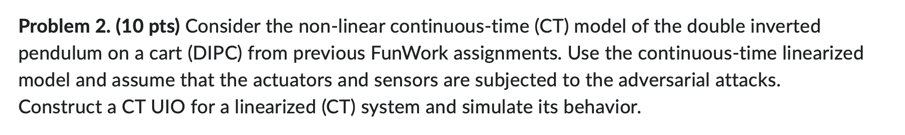

syms theta1 theta2 x_pos theta1_dot theta2_dot x_dot
syms theta1_ddot theta2_ddot x_ddot
syms u1 u2 u3 x

%get Results from Funwork1 means Model 
load("../Funwork4/Funwork4_Gery_Results.mat");

A = double(A_u3);
B = double(B_u3);
C = double(C_u3);
C_new = zeros(6, 6);
C_new(1:3, 1:3) = eye(3); % Position sensors (original)
C_new(4, 4) = 1;          % x_dot sensor
%C_new(5, 5) = 1;          % theta1_dot sensor

%C = eye(6);

C = C_new;

n = size(A, 1);
m = size(B, 2);
p = size(C, 1);

B2_uio = zeros(n,1); 
B2_uio(2,:) = 1;
B2_uio = B(:, 1);

D_sens = zeros(p, 1);
D_sens(1) = 1;

Obs_Matrix = [C*B2_uio, D_sens];
Target_Matrix = [B2_uio, zeros(n, 1)];

if rank(Obs_Matrix) == rank(B2_uio) + rank(D_sens)
    disp('UIO Condition Satisfied: Can decouple Both Attacks.');
    
    % Solve M * [CB D] = [B 0]
    M = Target_Matrix * pinv(Obs_Matrix);
    
else
    warning('Actuator-only decoupling.');
    M = B2_uio * pinv(C * B2_uio);
end

UIO Condition Satisfied: Can decouple Both Attacks.



% System Matrix A1
I_n = eye(n);
A1 = (I_n - M * C) * A;


% LQR Controller (stabilizes the deviation delta_x -> 0)
Q_lqr = diag([1000, 1000, 1000, 1, 1, 1]); 
R_lqr = 0.1;
K_fb = lqr(A, B, Q_lqr, R_lqr);

ctrl_poles = eig(A - B * K_fb)

ctrl_poles =  -29.7172 +15.1109i
 -29.7172 -15.1109i
  -4.2175 + 4.1373i
  -4.2175 - 4.1373i
 -10.3283 + 9.0784i
 -10.3283 - 9.0784i



desired_obs_poles = 6 * ctrl_poles;

L_uio = place(A1', C', desired_obs_poles)';

F_uio = A1 - L_uio * C;
obs_poles = eig(F_uio)

obs_poles = 1.0e+02 *

  -1.7830 + 0.9067i
  -1.7830 - 0.9067i
  -0.6197 + 0.5447i
  -0.6197 - 0.5447i
  -0.2531 + 0.2482i
  -0.2531 - 0.2482i


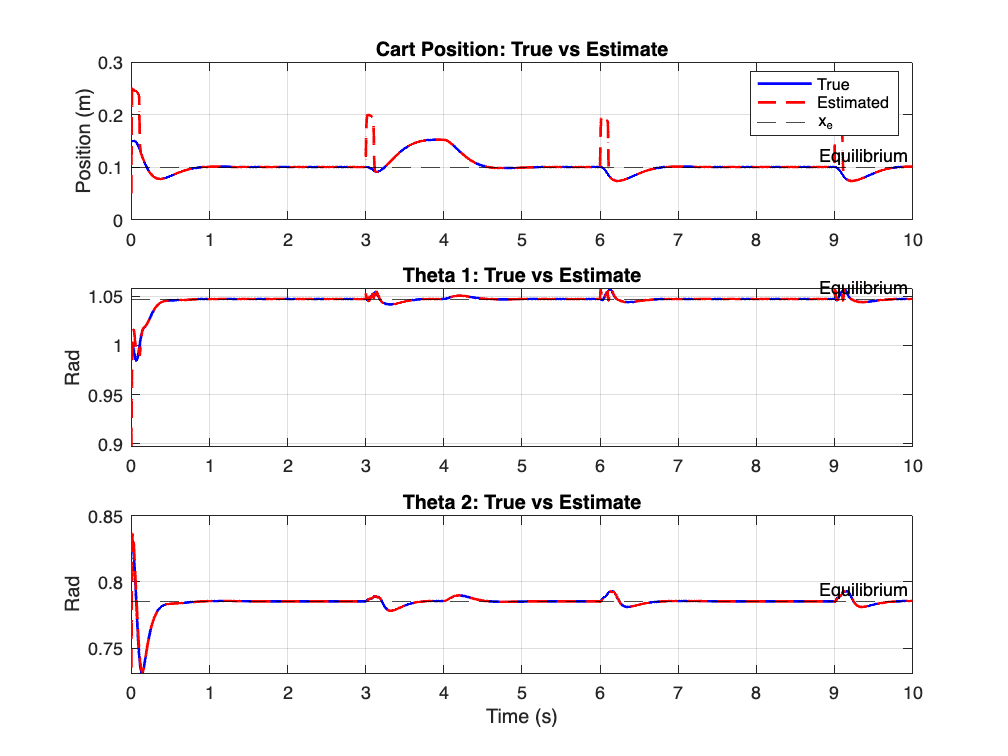


T_final = 10;

% Initial Condition (Perturbed from Equilibrium)
delta_x0 = [0.05; -0.05; 0.05; 0; 0; 0]; % Small deviation
x0_abs = xe_vals + delta_x0;                 % Absolute initial state


% q = (I-MC) * delta_x
q0 = (I_n - M*C) * delta_x0 - 0.1;
% with zero init state
%q0 = zeros(n, 1);

aug_state_0 = [x0_abs; q0];

% Attack on u1 (Force)
attack_actuator = @(t) [5*(t >= 3 && t <= 4); 0; 0]; %[2 * sin(3*t); 0; 0];
%attack_actuator = @(t) [2 * sin(3*t); 0; 0];
% Attack on Sensors (Noise/Bias)
attack_sensor = @(t) [0.1 * (mod(t, 3) < 0.1); 0; 0; 0; 0; 0];

% 7. Run Non-Linear Simulation
if isa(f_u3, 'sym')
    f_num = matlabFunction(f_u3, 'Vars', {state_vector, input_vector});
else
    f_num = f_u3;
end

% Simulation
[t_out, x_out] = ode45(@(t, x) sys_dynamics_delta(t, x, f_num, ...
                       A, B, C, M, K_fb, L_uio, ...
                       xe_vals, ue, attack_actuator, attack_sensor), ...
                       [0 T_final], aug_state_0);

% Signals for Plotting
X_abs_true = x_out(:, 1:n);
Q_hist = x_out(:, n+1:end);
X_abs_est = zeros(size(X_abs_true));

for i = 1:length(t_out)
    t = t_out(i);
    
    % Measure Absolute Output
    y_abs = C * X_abs_true(i,:)' + attack_sensor(t);
    
    % Calculate Output Deviation
    y_e = C * xe_vals;
    delta_y = y_abs - y_e;
    
    % Reconstruct Deviation Estimate: delta_hat = q + M * delta_y
    delta_x_hat = Q_hist(i,:)' + M * delta_y;
    
    % Convert back to Absolute Estimate
    X_abs_est(i,:) = (xe_vals + delta_x_hat)';
end

figure('Name', 'Problem 2: CT UIO');

% 1. Cart Position (x)
subplot(3,1,1);
plot(t_out, X_abs_true(:,1), 'b', 'LineWidth', 1.5); hold on;
plot(t_out, X_abs_est(:,1), 'r--', 'LineWidth', 1.5);
yline(xe_vals(1), 'k--', 'Equilibrium');
title('Cart Position: True vs Estimate');
legend('True', 'Estimated', 'x_e'); 
ylabel('Position (m)'); grid on;

% 2. Pendulum 1 Angle (theta1)
subplot(3,1,2);
plot(t_out, X_abs_true(:,2), 'b', 'LineWidth', 1.5); hold on;
plot(t_out, X_abs_est(:,2), 'r--', 'LineWidth', 1.5);
yline(xe_vals(2), 'k--', 'Equilibrium');
title('Theta 1: True vs Estimate');
ylabel('Rad'); grid on;

% 3. Pendulum 2 Angle (theta2)
subplot(3,1,3);
plot(t_out, X_abs_true(:,3), 'b', 'LineWidth', 1.5); hold on;
plot(t_out, X_abs_est(:,3), 'r--', 'LineWidth', 1.5);
yline(xe_vals(3), 'k--', 'Equilibrium');
title('Theta 2: True vs Estimate');
ylabel('Rad'); grid on;
xlabel('Time (s)');


% Dynamics 
function dX = sys_dynamics_delta(t, aug, f_plant, A, B, C, M, K, L, xe_vals, ue, att_u, att_y)
    n = size(A,1);
    x_abs = aug(1:n);      % Absolute Non-linear State
    q = aug(n+1:end);      % Observer State (Estimating Deviations)
    
    % --- 1. Calculate Deviations from Measurement ---
    y_abs_meas = C * x_abs + att_y(t); % y_meas = Cx + D2*u3
    y_e = C * xe_vals;                      % Nominal Equilibrium Output
    delta_y = y_abs_meas - y_e;        % Deviation y - ye
    
    % delta_x_hat = q + M * delta_y
    delta_x_hat = q + M * delta_y;
    

    % The controller tries to drive delta_x to 0 (return to equilibrium)
    delta_u_known = -K * delta_x_hat; 
    
    % Plant Input = Equilibrium + Control + Attack
    % Note: u_attack is treated as the "Unknown Input" u2 in the delta model
    u_total = ue + delta_u_known + att_u(t);
    
    dx_abs = f_plant(x_abs, u_total);

    % delta_dot = A*delta + B*delta_u + B*w
    % q_dot = (I-MC)(A*q + A*M*delta_y + B*delta_u_known) + L(delta_y - C*delta_hat)
    
    I_MC = eye(n) - M*C;
    term_model = I_MC * (A*q + A*M*delta_y + B*delta_u_known);
  
    delta_y_hat = C * delta_x_hat; 
    term_innov = L * (delta_y - delta_y_hat);
    
    dq = term_model + term_innov;
    
    dX = [dx_abs; dq];
end



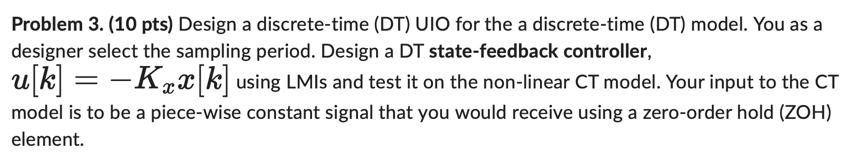

clear all; clc; close all;


load("../Funwork4/Funwork4_Gery_Results.mat"); 

Ts = 0.01; % Sampling Time
xe = double(xe_vals(:));
ue = double(ue(:));

% Continuous Matrices
A_ct = double(A_u3);
B_ct = double(B_u3);

C_ct = eye(5,6); 

n = size(A_ct, 1);
m = size(B_ct, 2);
p = size(C_ct, 1);

% Discretize Plant (ZOH)
sys_ct = ss(A_ct, B_ct, C_ct, zeros(p,m));
sys_dt = c2d(sys_ct, Ts, 'zoh');
Ad = sys_dt.A;
Bd = sys_dt.B;
Cd = sys_dt.C;

Ed = Bd(:, 1); 
% Sensor Attack Matrix (if applicable, e.g., on position x)
D2 = zeros(p, 1); 
D2(1) = 1; % Example: Attack on first sensor

% 2. Compute M (Decoupling Matrix)
Obs_Matrix = [Cd*Ed, D2];
Target_Matrix = [Ed, zeros(n, 1)];

if rank(Obs_Matrix) == rank(Ed) + rank(D2)
    disp('UIO Existence Condition Satisfied.');
    M = Target_Matrix * pinv(Obs_Matrix);
else
    warning('Full decoupling not possible. Decoupling state input only.');
    M = Ed * pinv(Cd * Ed);
end

UIO Existence Condition Satisfied.



I_n = eye(n);
A1 = (I_n - M * Cd) * Ad;



alpha = 0.5; 

% Determine disturbance dimension r from D2d (should be 1 based on your D2)
r = size(D2, 2); 
n = size(A1, 1);

cvx_begin sdp quiet
    variable P(n,n) symmetric
    variable Z(n, size(C_ct,1))
    
    % Omega21_T = [ PA1 - ZC,  -ZD ]  
    Phi = P*A1 - Z*C_ct;
    Omega21_T = [Phi, -Z*D2]; % Size: n x (n+r) (6x7)
    
    Omega22 = [ -(1-alpha)*P,      zeros(n, r);
                 zeros(r, n),      -alpha*eye(r) ];
             
    subject to
        P >= eye(n) * 1e-4; 
    
        
        [ -P,           Omega21_T;
          Omega21_T',   Omega22   ] <= 0;
cvx_end

if strcmp(cvx_status, 'Solved')
    L_disc = P \ Z;
    fprintf('Discrete UIO Gain Found.\n');
else
    error('LMI Failed. Try reducing alpha or checking D2d dimensions.');
end

Discrete UIO Gain Found.




if strcmp(cvx_status, 'Solved')
    L_uio = P \ Z;
    fprintf('Discrete UIO Gain Found.\n');
    
    % Compute Final Matrices
    Fd = A1 - L_uio * C_ct;
    Td = eye(6) - M * C_ct;
    Hd = M;
    Kd_obs = L_uio + Fd * M;
    
    disp('Eigenvalues of Discrete Error Dynamics (should be inside unit circle):');
    disp(abs(eig(Fd)));
else
    error('LMI Failed. Try reducing alpha.');
end

Discrete UIO Gain Found.


Eigenvalues of Discrete Error Dynamics (should be inside unit circle):


    0.3199
    0.5845
    0.0350
    0.0000
    0.0000
    0.0000






cvx_begin sdp quiet
    variable Q_ctrl(n,n) symmetric
    variable Y_ctrl(m,n)
    

    rho_ctrl = 0.99; 
    
    minimize(norm(Y_ctrl, 'fro'))
    subject to
        Q_ctrl >= eps * I_n;
        [ -rho_ctrl^2 * Q_ctrl, (Ad * Q_ctrl - Bd * Y_ctrl)' ;
          (Ad * Q_ctrl - Bd * Y_ctrl), -Q_ctrl ] <= -eps * eye(2*n);
cvx_end

if strcmp(cvx_status, 'Solved')
    K_dt = Y_ctrl / Q_ctrl;
    disp('Controller Gain K Found.');
else
    error('CVX Failed to find Controller gain.');
end

Controller Gain K Found.


A_cl = Ad - Bd * K_dt;
poles_ctrl = eig(A_cl)

poles_ctrl =    0.9403 + 0.0000i
   0.9891 + 0.0082i
   0.9891 - 0.0082i
   0.9751 + 0.0000i
   0.9724 + 0.0000i
   0.9654 + 0.0000i



T_final = 10;
steps = floor(T_final / Ts);

x_abs = xe-0.1; 

z_state = zeros(n, 1);

% Storage
Hist_Time = [];
Hist_X_True = [];
Hist_X_Est = [];

if isa(f_u3, 'sym')
    f_num = matlabFunction(f_u3, 'Vars', {state_vector, input_vector});
else
    f_num = f_u3;
end

attack_fun = @(t) 10 * (t >= 1.5 && t <= 2.0);

attack_sensor_fun = @(t) [0.2 * (t >= 4.0 && t <= 5.5); 0; 0; 0; 0];

fprintf('Starting Hybrid Simulation...\n');

Starting Hybrid Simulation...



for k = 1:steps
    t_curr = (k-1)*Ts;
    t_next = k*Ts;    

    y_attack_val = attack_sensor_fun(t_curr);

    y_meas_abs = Cd * x_abs + y_attack_val;     

    y_dev = y_meas_abs - Cd * xe;

    x_hat_dev = z_state + M * y_dev;   

    x_hat_abs = xe + x_hat_dev;
    
    % u_dev[k] = -K * x_hat_dev[k]
    u_dev = -K_dt * x_hat_dev;
    u_applied = ue + u_dev;
    
    Hist_Time = [Hist_Time; t_curr];
    Hist_X_True = [Hist_X_True; x_abs'];
    Hist_X_Est = [Hist_X_Est; x_hat_abs'];
     
    ode_sys = @(t, x) plant_dynamics_wrapper(t, x, u_applied, f_num, attack_fun);
    [~, X_ode] = ode15s(ode_sys, [t_curr, t_next], x_abs);
    
    x_abs = X_ode(end, :)';
       
    term_pred = (I_n - M*Cd) * (Ad * x_hat_dev + Bd * u_dev);
    
    y_hat = Cd * x_hat_dev;
    term_innov = L_uio * (y_dev - y_hat);
    
    z_state = term_pred + term_innov;
end

disp('Simulation Complete.');

Simulation Complete.


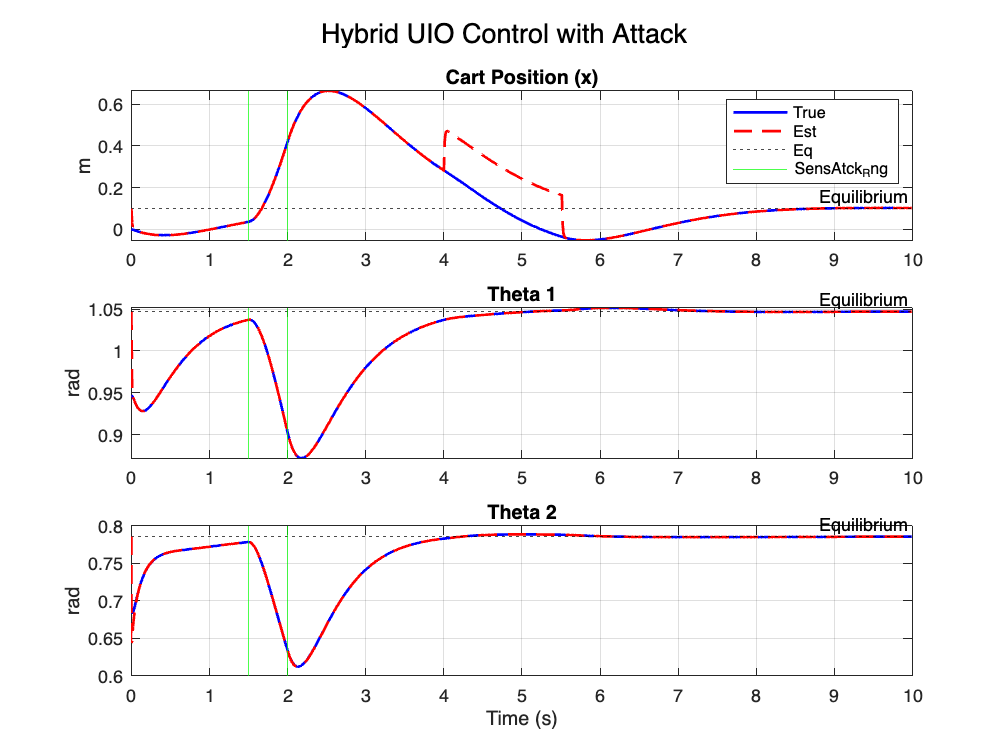


figure('Color', 'w', 'Name', 'Problem 3 Results');
sgtitle('Hybrid UIO Control with Attack');

% Plot Positions
state_indices = [1, 2, 3];
titles = {'Cart Position (x)', 'Theta 1', 'Theta 2'};
ylabels = {'m', 'rad', 'rad'};

for i = 1:3
    idx = state_indices(i);
    subplot(3,1,i);
    plot(Hist_Time, Hist_X_True(:,idx), 'b', 'LineWidth', 1.5); hold on;
    plot(Hist_Time, Hist_X_Est(:,idx), 'r--', 'LineWidth', 1.5);
    yline(xe(idx), 'k:', 'Equilibrium');
    xline(1.5, 'g-' );
    xline(2.0, 'g-');
    
    ylabel(ylabels{i}); title(titles{i}); grid on;
    if i==1, legend('True', 'Est', 'Eq', 'SensAtck_Rng'); end
end
xlabel('Time (s)');

function dx = plant_dynamics_wrapper(t, x, u_const, f_func, att_func)
   f_att = att_func(t);   
    u_total = u_const;
    u_total(1) = u_total(1) + f_att;    
    dx = f_func(x, u_total);
end

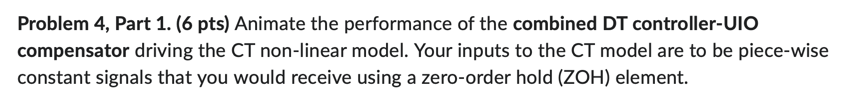

## Output for 3D Animation

%  physical parameters
l1 = 0.5; 
l2 = 0.75; 
g = 9.81;

% Cart dimensions 
cart_width = 0.5;
cart_height = 0.25;

T_obs = Hist_Time;
X = Hist_X_True;

x_res = timeseries(X(:,1), T_obs);
Theta1_res = timeseries(X(:,2), T_obs);
Theta2_res = timeseries(X(:,3), T_obs);

